# q Investigation

Live script to find alpha small q, given alpha Q1 Q2. From Q1 and Q1/Q2 Investigation we get aQ1 = 0.60 and aQ2 = 0.50.

Produced using qMaxEventsx, which comes from VBWIMq.

*Can also use qMaxEvents which comes from ? i forget - not as complete*

This is part of an initial effort to estimate alpha q using OBSERVED WIM. We will then move to sims

- For now we use the same bridge lengths/configs as in AGB 2002/005

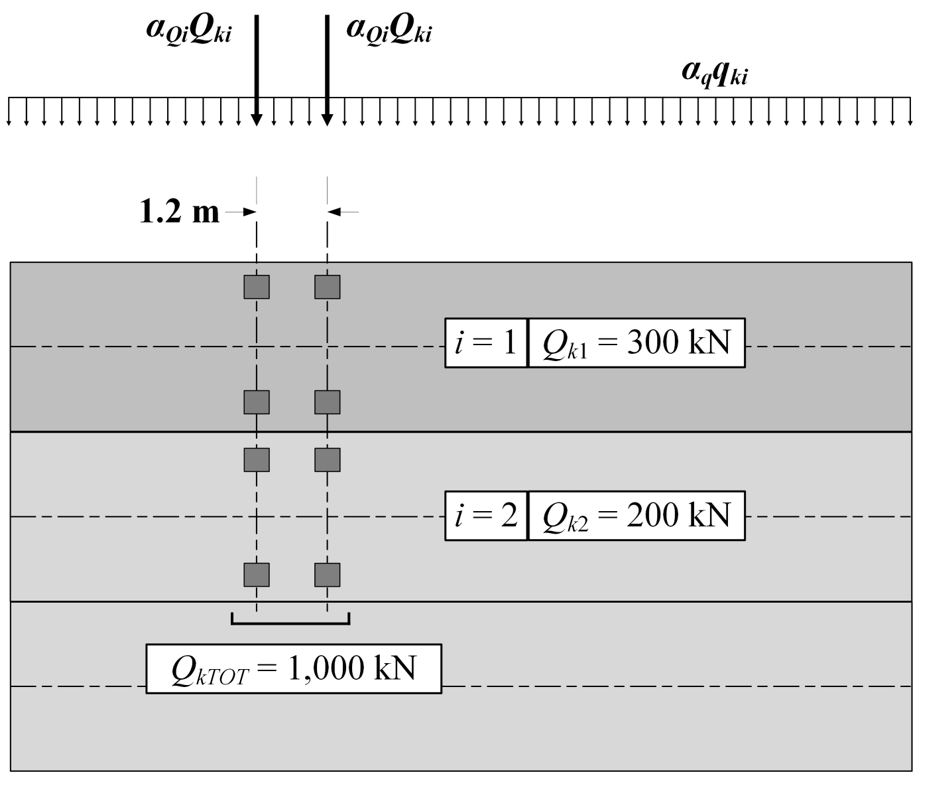

To save time, user can choose to skip the first 4 steps by loading qMaxEventsxMax, qMaxEventsxpd, qMaxEventsxy_values, and qMaxEventsxx_values.

In this case, the default Input values in Step 1 are used. Only available for qMaxEventsx (not qMaxEvents).

% Initial commands
clear, clc, close all
% This function loads the variable 'MaxEvents' which is produced by 'MATSimAxles'
load('qMaxEventsx.mat');
load('ESIAWIM.mat');
load('InflWIM.mat');

### Step 1: Input desired filters/parameters

% Select which year to analyze %Years = 2011:2019;
Years = 0;
% Select stations (locations) to analyze %Stations = [408 409 405 406 402 415 416];
Stations = 0;

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
ClassType = {'All', 'ClassOW', 'Class'};
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassT = {'All', 'Classified+', 'Classified'};

% Must define Action Effects
%AE = {'Mp', 'Mn', 'V'};

### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = MaxEvents.SITE == Stations;
    MaxEvents(~any(y,2),:) = [];
end
if Years > 0
    y = year(MaxEvents.DTS) == Years;
    MaxEvents(~any(y,2),:) = [];
end

### Step 3: Build Structure with Block Maxima

% Convert ClassT to m (number) form m = 1 is All, m = 2 is ClassOW, m = 3 is Class
MaxEvents.m(strcmp(MaxEvents.ClassT,"All")) = 1;
MaxEvents.m(strcmp(MaxEvents.ClassT,"ClassOW")) = 2;
MaxEvents.m(strcmp(MaxEvents.ClassT,"Class")) = 3; MaxEvents.ClassT = [];

% For each Influence case
for r = 1:length(Infl.Names)
    
    % Reset MaxEvents and select r
    MaxEventsSub = MaxEvents(MaxEvents.InfCase == r,:);
    % Transform AxTandem into Array (necessary for splitapply)
    Z = MaxEventsSub;
    Z.DTS = datenum(Z.DTS);
    Z = table2array(Z);
    
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        % Filter based on Class - MaxEvents is compromised after this (deleting entries)
        if strcmp(Class,'ClassOW')
            MaxEventsSub(MaxEventsSub.m == 1,:) = []; %#ok<*SAGROW>
            Z(Z(:,end) == 1,:) = [];
        elseif strcmp(Class,'Class')
            MaxEventsSub(MaxEventsSub.m == 1,:) = [];
            Z(Z(:,end) == 1,:) = [];
            MaxEventsSub(MaxEventsSub.m == 2,:) = [];
            Z(Z(:,end) == 2,:) = [];
        end
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            % Initialize
            Max(r).(Class).(BlockM) = [];
            
            if strcmp(BlockM,'Daily')
                
                % Make groups out of unique locations and days
                [Gr, GrIDDay, GrIDSITE, GrIDInf] = findgroups(dateshift(MaxEventsSub.DTS,'start','day'),MaxEventsSub.SITE,MaxEventsSub.InfCase);
               
            elseif strcmp(BlockM,'Weekly')
                
                [Gr, GrIDWeek, GrIDSITE, GrIDInf] = findgroups(dateshift(MaxEventsSub.DTS,'start','week'),MaxEventsSub.SITE,MaxEventsSub.InfCase);
                
            else
                
                [Gr, GrIDYear, GrIDSITE, GrIDInf] = findgroups(year(MaxEventsSub.DTS),MaxEventsSub.SITE,MaxEventsSub.InfCase);
                
            end
            
            % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
            Max(r).(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
            % Transform back into table form
            Max(r).(Class).(BlockM) = array2table(Max(r).(Class).(BlockM));
            Max(r).(Class).(BlockM).Properties.VariableNames = {'R', 'SITE', 'Max', 'InfCase', 'DayRank', 'L1Veh', 'L2Veh', 'L1Load', 'L2Load', 'L1Ax', 'L2Ax', 'L1Sp', 'L2Sp', 'DTS', 'm'};
            Max(r).(Class).(BlockM).DTS = datetime(Max(r).(Class).(BlockM).DTS,'ConvertFrom',"datenum"); Max(r).(Class).(BlockM).R = [];
            
        end
    end
end

#### Step 4: Curve Fitting

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal', 'ExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
%x_values = 0:250:50000;

% For each Influence Case
for r = 1:length(Infl.Names)

    % Fit Block Maxima to Normal Curve
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            for k = 1:length(DistTypes)
                Dist = DistTypes{k};
                
                pd(r).(Class).(BlockM).(Dist) = fitdist(Max(r).(Class).(BlockM).Max,Dist);
                Top = ceil(max(Max(r).(Class).(BlockM).Max)/500)*500;
                Bot = floor(min(Max(r).(Class).(BlockM).Max)/500)*500;
                TBDiff = Top-Bot;
                x_values(r).(Class).(BlockM) = Bot:round(TBDiff/100,-1):Top;
                y_values(r).(Class).(BlockM).(Dist).PDF_Fit = pdf(pd(r).(Class).(BlockM).(Dist),x_values(r).(Class).(BlockM));
                y_values(r).(Class).(BlockM).(Dist).CDF_Fit = cdf(pd(r).(Class).(BlockM).(Dist),x_values(r).(Class).(BlockM));
                
                
                if strcmp(BlockM,'Daily')
                    y_values(r).(Class).('Weekly').(Dist).CDF_D2W = y_values(r).(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                    y_values(r).(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values(r).(Class).('Weekly').(Dist).CDF_D2W)];
                    y_values(r).(Class).('Yearly').(Dist).CDF_D2Y = y_values(r).(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                    y_values(r).(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y)];
                    
                    if strcmp(Dist,'Normal')
                        mu = trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,x_values(r).(Class).(BlockM));
                        sigma = sqrt(trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,(x_values(r).(Class).(BlockM)-mu).^2));
                        pd(r).(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                        
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,x_values(r).(Class).(BlockM));
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,(x_values(r).(Class).(BlockM)-mu).^2));
                        pd(r).(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    elseif strcmp(Dist,'Lognormal')
                        mu = trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,x_values(r).(Class).(BlockM));
                        sigma = sqrt(trapz(y_values(r).(Class).('Weekly').(Dist).CDF_D2W,(x_values(r).(Class).(BlockM)-mu).^2));
                        zeta = sqrt(log(1+(sigma/mu)^2));
                        lambda = log(mu)-0.5*zeta^2;
                        pd(r).(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                        
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,x_values(r).(Class).(BlockM));
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_D2Y,(x_values(r).(Class).(BlockM)-mu).^2));
                        zeta = sqrt(log(1+(sigma/mu)^2));
                        lambda = log(mu)-0.5*zeta^2;
                        pd(r).(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    end
                    
                elseif strcmp(BlockM,'Weekly')
                    y_values(r).(Class).('Yearly').(Dist).CDF_W2Y = y_values(r).(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                    y_values(r).(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y)];
                    
                    if strcmp(Dist,'Normal')
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,x_values(r).(Class).(BlockM));
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,(x_values(r).(Class).(BlockM)-mu).^2));
                        pd(r).(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                        
                    elseif strcmp(Dist,'Lognormal')
                        mu = trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,x_values(r).(Class).(BlockM));
                        sigma = sqrt(trapz(y_values(r).(Class).('Yearly').(Dist).CDF_W2Y,(x_values(r).(Class).(BlockM)-mu).^2));
                        zeta = sqrt(log(1+(sigma/mu)^2));
                        lambda = log(mu)-0.5*zeta^2;
                        pd(r).(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                        
                    end
                end
            end
        end
    end
end

### Step 4: Plot Block Maxima

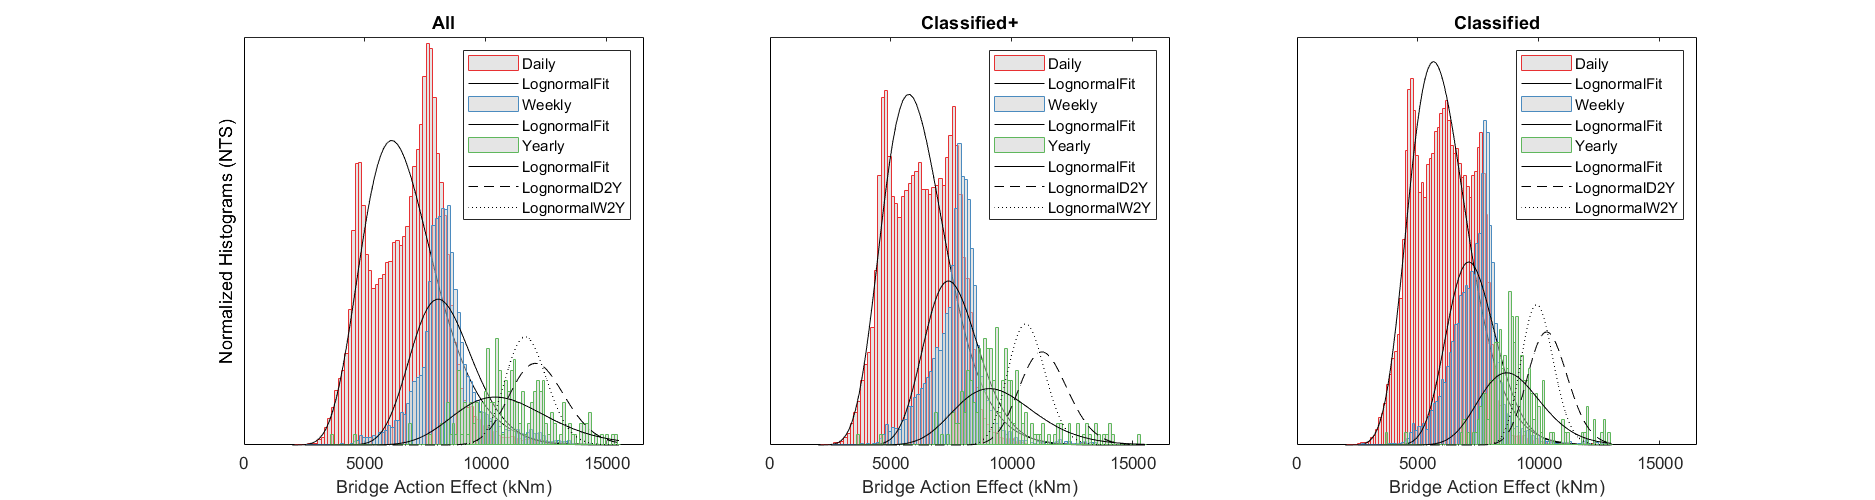

% Initial commands
clear, clc, close all
% Inputs
BM = {'Daily', 'Weekly', 'Yearly'};             % j
ClassType = {'All', 'ClassOW', 'Class'};        % i
ClassT = {'All', 'Classified+', 'Classified'};
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};
load('qMaxEventsxMax.mat')
load('qMaxEventsxpd.mat')
load('qMaxEventsxy_values.mat')
load('qMaxEventsxx_values.mat')
load('ESIAWIM.mat');
load('InflWIM.mat');

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];

for r = 12;
    
    figure('Position',[0 0 1500 400]);

    for i = 1:length(ClassType)
        Class = ClassType{i};

        subplot(1,3,i)
        hold on

        for j = 1:length(BM)
            BlockM = BM{j};

            % X Stuff
            Step = 250;
            LimitL = 0;
            LimitR = 20000;
            %X = LimitL:Step:LimitR;
            X = x_values(r).(Class).(BlockM);
            x = X(1:end-1) + diff(X);

            y = histcounts(Max(r).(Class).(BlockM).Max,'BinEdges',X,'normalization','pdf');
            bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)

            for k = 2
                Dist = DistTypes{k};
                plot(X,y_values(r).(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])

                if strcmp(BlockM,'Yearly') & (~strcmp(Dist,'ExtremeValue') | ~strcmp(Dist,'GeneralizedExtremeValue'))
                    plot(X,pdf(pd(r).(Class).D2Y.(Dist),X)/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                    plot(X,pdf(pd(r).(Class).W2Y.(Dist),X)/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
                end

            end
           
            xlim([0 max(x_values(r).All.(BlockM))+100*max(x_values(r).All.(BlockM))/1500])
             
        end

        % Set Plot Details
        set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
        box on
        if i == 1
            ylabel('Normalized Histograms (NTS)')
        end
        xlabel('Bridge Action Effect (kNm)')
        title([ClassT{i}])
        legend('location','northeast')

    end
end

#### *Block Maxima Compared between each other*

### Step 5: Probability Paper Plotting & Tail Fitting Methods

When we apply the above equations, we are assuming the maximums are normally or log-normally distributed. We should evaluate the fit with a probability paper plot.

PlotB = 0;

% For each Influence Case
for r = 1:length(Infl.Names);
    
    figure('Position',[0 0 1500 400]);
    
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            
            [MaxECDF, MaxECDFRank] = ecdf(Max(r).(Class).(BlockM).Max); MaxECDFRank = MaxECDFRank'; MaxECDF(1) = []; MaxECDFRank(1) = [];
            
            
            mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
            
            x2 = norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1));
            y2 = log(MaxECDFRank);
            
            md2 = fitlm(x2(round(length(x2)*3/4):length(x2)),y2(round(length(x2)*3/4):length(x2)),'linear');
            
            if PlotB == 1
                subplot(1,3,i)
                hold on
                scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,C(j,:),'filled','DisplayName','Max Data');
                plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',C(j,:),'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);
                box on
                y1 = ylim;
                text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",C(j,:))
            end

            Fit(i,j,r) = mdl.Rsquared.Ordinary*100;
            
        end
        
        if PlotB == 1
            if i == 1
                ylabel('log[ Total Load Effect (kNm) ]')
            end
            xlabel('Standard Normal Percentile')
            %legend('Location', 'southeast')
            title([ClassT{i}])
        end
    end
end

#### Lognormal Probability Paper

### Step 6: Summarize $\alpha_Q$ Estimates

*The alpha we are finding and putting in the table right now is some kind of composite alpha...*

*We need to add AQ1 and AQ2 to get the real Aq...*

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
Alpha = 0.7;
AQ1 = 0.6;
AQ2 = 0.5;
% For Plot
ClassP = 'Class';
BlockMP = 'Weekly';

% For each Influence Case
for r = 1:length(Infl.Names)
    
    % Initialize SumTable
    ST(r).SumTableLogNorm = array2table(zeros(6,length(BM)*length(ClassType)));
    ST(r).SumTableLogNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{1}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{3}], [BM{2} ' ' ClassType{1}],...
        [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{3}], [BM{1} ' ' ClassType{1}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{3}]};
    ST(r).SumTableLogNorm.Properties.RowNames = {'Em', 'Ed', 'Ed (%ile*10)', 'LNFit (%)', 'AlphaQLN', 'AlphaqLN'};

    ST(r).SumTableLogNormComp = array2table(zeros(2,(length(BM)-1)*length(ClassType)));
    ST(r).SumTableLogNormComp.Properties.RowNames = {'AlphaQLN', 'AlphaqLN'};
    ST(r).SumTableLogNormComp.Properties.VariableNames = {['W2Y ' ClassType{1}],['W2Y ' ClassType{2}],['W2Y ' ClassType{3}],['D2Y ' ClassType{1}],['D2Y ' ClassType{2}],['D2Y ' ClassType{3}]};
    
    for i = 1:length(ClassType)
        Class = ClassType{i};
        
        for j = 1:length(BM)
            BlockM = BM{j};
            
            Em = mean(Max(r).(Class).(BlockM).Max);
            Stdev = std(Max(r).(Class).(BlockM).Max);
            COV = Stdev/Em;
            Delta2 = log(COV^2+1);
            N5 = prctile(Max(r).(Class).(BlockM).Max,95);
            Dist95N = norminv(0.95,pd(r).(Class).(BlockM).Normal.mu,pd(r).(Class).(BlockM).Normal.sigma);
            Dist95LN = logninv(0.95,pd(r).(Class).(BlockM).Lognormal.mu,pd(r).(Class).(BlockM).Lognormal.sigma);
            
            EdN = Em*(1+Alpha*Beta.(BlockM)*COV);
            AQN = EdN/(ESIA.Total(r));
            AqN = ((EdN/1.5)-AQ1*ESIA.EQ(1,r)-AQ2*ESIA.EQ(2,r))/(ESIA.Eq(r));
            
            EdLN = Em*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);
            AQLN = EdLN/(ESIA.Total(r));
            AqLN = ((EdLN/1.5)-AQ1*ESIA.EQ(1,r)-AQ2*ESIA.EQ(2,r))/(ESIA.Eq(r));
            
            % Find %ile corresponding to Ed
            N5 = prctile(Max(r).(Class).(BlockM).Max,95);
            I95 = invprctile(Max(r).(Class).(BlockM).Max,EdLN);
            
            ST(r).SumTableLogNorm.([BlockM ' ' Class]) = [Em; EdLN; I95*10; Fit(i,j,r); AQLN; AqLN];
            
            if strcmp(BlockM,'Weekly')
                pdx = pd(r).(Class).W2Y.Lognormal;
                Delta2 = pdx.sigma^2;
                Em = exp(pdx.mu+0.5*Delta2);
                ST(r).SumTableLogNormComp.(['W2Y ' Class]) = [Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(ESIA.Total(r)); (((Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2))/1.5)-AQ1*ESIA.EQ(1,r)-AQ2*ESIA.EQ(2,r))/(ESIA.Eq(r))];
            elseif strcmp(BlockM,'Daily')
                pdx = pd(r).(Class).D2Y.Lognormal;
                Delta2 = pdx.sigma^2;
                Em = exp(pdx.mu+0.5*Delta2);
                ST(r).SumTableLogNormComp.(['D2Y ' Class]) = [Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(ESIA.Total(r)); (((Em*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2))/1.5)-AQ1*ESIA.EQ(1,r)-AQ2*ESIA.EQ(2,r))/(ESIA.Eq(r))];
            end
            
            if strcmp(Class,ClassP) & strcmp(BlockM,BlockMP)
                PlotAq(r) = ST(r).SumTableLogNorm{'AlphaqLN',[BlockM ' ' Class]};
                PlotAQ(r) = ST(r).SumTableLogNorm{'AlphaQLN',[BlockM ' ' Class]};
            end
        end
    end
end
r = 12;
format bank
disp(ST(r).SumTableLogNorm)

                    Yearly All    Yearly ClassOW    Yearly Class    Weekly All    Weekly ClassOW    Weekly Class    Daily All    Daily ClassOW    Daily Class
                    __________    ______________    ____________    __________    ______________    ____________    _________    _____________    ___________

    Em               10905.21         9510.13          8945.59        8325.13         7632.79          7314.87       6660.25        6183.13         6024.05  
    Ed               18491.40        16706.99         14029.18       14953.48        13249.63         12233.81      16273.01       14380.66        13284.40  
    Ed (%ile*10)

disp(ST(r).SumTableLogNormComp)

                W2Y All    W2Y ClassOW    W2Y Class    D2Y All    D2Y ClassOW    D2Y Class
                _______    ___________    _________    _______    ___________    _________

    AlphaQLN     0.60         0.54          0.50        0.67         0.61          0.54   
    AlphaqLN     0.65         0.51          0.41        0.81         0.68          0.52   



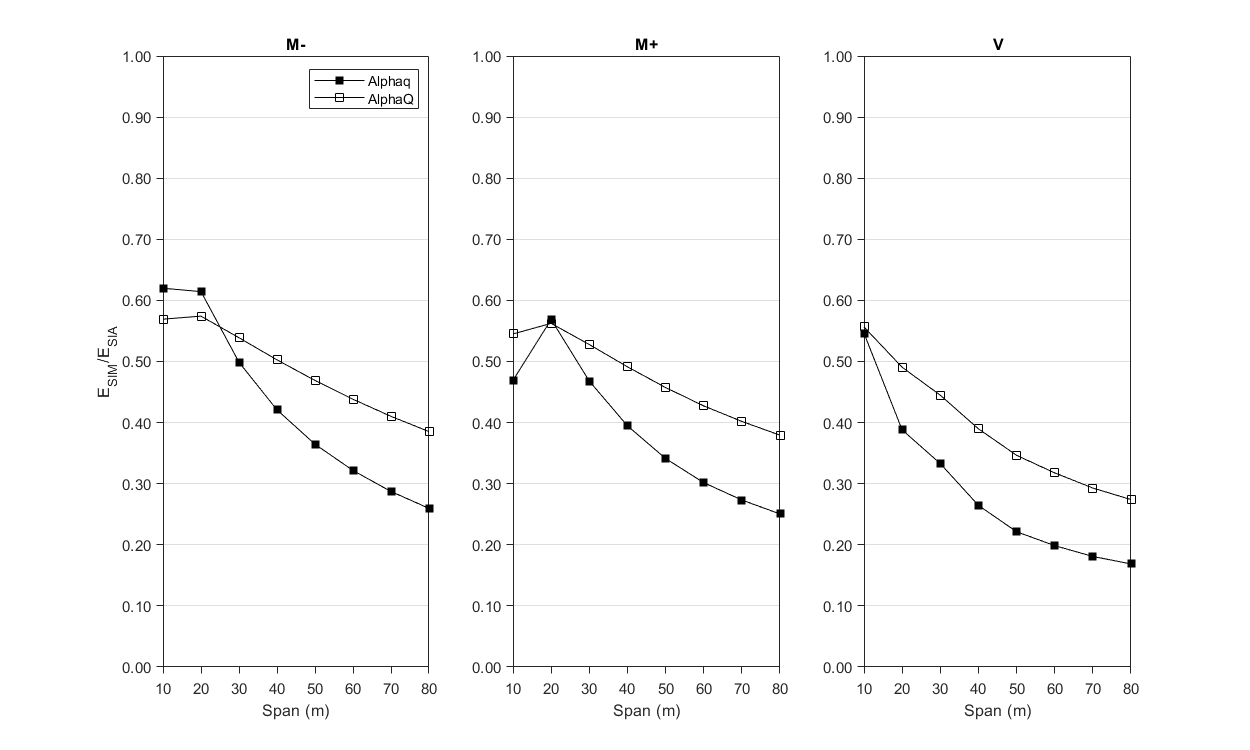

% Collect all Alphaq Estimates for each IL and display
figure('Position',[0 0 1000 600]);
Title{1} = 'M-'; Title{2} = 'M+'; Title{3} = 'V';
for i = 1:3
    subplot(1,3,i)
    hold on
    plot(10:10:80,PlotAq(((i-1)*8+1):((i)*8)),'-s','Color','k','MarkerEdgeColor','none','MarkerFaceColor','k','MarkerSize',7,'DisplayName','Alphaq')
    plot(10:10:80,PlotAQ(((i-1)*8+1):((i)*8)),'-s','Color','k','MarkerEdgeColor','k','MarkerFaceColor','none','MarkerSize',7,'DisplayName','AlphaQ')
    ytickformat('%.2f'); yticks(0:0.1:1); xticks(10:10:80); set(gca,'TickDir','out'); set(gca,'YGrid','on')
    xlabel('Span (m)')
    a = gca; set(a,'box','off','color','none');
    % create new, empty axes with box but without ticks
    b = axes('Position',get(a,'Position'),'box','on','xtick',[],'ytick',[]);
    % set original axes as active, and link axes in case of zooming
    axes(a); linkaxes([a b]);

    % Set axis limits
    ylim([0 1]); xlim([10 80])
    % Y-axis only for the leftmost (first) plot
    if i == 1
        ylabel('E_{SIM}/E_{SIA}')
        yh = get(gca,'ylabel'); % handle to the label object
        p = get(yh,'position'); % get the current position property
        p(1) = 0.9*p(1);          % double the distance,
        % negative values put the label below the axis
        set(yh,'position',p)   % set the new position
        legend('location','northeast')
    end
    title([Title{i}])
end

#### Weekly Class Results by Span and AE | for Alphaq, AlphaQ1 is set at 0.60 and AlphaQ2 is set at 0.50

### Step 7: Populate WIM, a comparison with AGB and MAT Results Variables

% First choose which result we will use (try Lognormal Weekly and Yearly)

Section = 'Box';

UniqNames = unique(Infl.Names,'stable');
ColumnNames = {'EQ1','EQ2','Eq','YClass','YClassOW','YAll','WClass','WClassOW','WAll','E'};

% Initialize the final matrix/table
X = NaN(8,length(ColumnNames));
XT = array2table(X,'VariableNames',ColumnNames);
SpanDiv = 10;

for r = 1:length(Infl.Names)
    % Get InfName (call it Temp)
    Temp = UniqNames{r}; %Fixed 26.5.20
    % Get Span from InfName
    Span = str2num(Temp(end-1:end));
    % Get Action Effect from InfName
    AE = Temp(1:end-2);
    
    try
        if istable(WIM.(Section).(AE))
            WIM.(Section).(AE).YClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly Class')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).YClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly ClassOW')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).YAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).WClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly Class')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).WClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly ClassOW')(end)*(ESIA.Total(r));
            WIM.(Section).(AE).WAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
            
            WIM.(Section).(AE).E(Span/SpanDiv) = ESIA.Total(r);
            WIM.(Section).(AE).Eq(Span/SpanDiv) = ESIA.Eq(r);
            WIM.(Section).(AE).EQ1(Span/SpanDiv) = ESIA.EQ(1,r);
            WIM.(Section).(AE).EQ2(Span/SpanDiv) = ESIA.EQ(2,r);
            
        end
    catch
        WIM.(Section).(AE) = XT;
        
        WIM.(Section).(AE).YClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly Class')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).YClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly ClassOW')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).YAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).WClass(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly Class')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).WClassOW(Span/SpanDiv) = ST(r).SumTableLogNorm.('Weekly ClassOW')(end)*(ESIA.Total(r));
        WIM.(Section).(AE).WAll(Span/SpanDiv) = ST(r).SumTableLogNorm.('Yearly All')(end)*(ESIA.Total(r));
        
        WIM.(Section).(AE).E(Span/SpanDiv) = ESIA.Total(r);
        WIM.(Section).(AE).Eq(Span/SpanDiv) = ESIA.Eq(r);
        WIM.(Section).(AE).EQ1(Span/SpanDiv) = ESIA.EQ(1,r);
        WIM.(Section).(AE).EQ2(Span/SpanDiv) = ESIA.EQ(2,r);
        
    end
end

### What types of vehicles are involved, what times of day, and what speeds?

close all,
r = 12;

% Get histogram of speeds
histogram(hour(Max(r).All.Daily.DTS),100,'normalization','pdf')
box on
set(gca,'ytick',[],'yticklabel',[])
ylabel('Normalized Histograms')
xlabel('Hour of the Day')

histogram(Max(r).All.Daily.L1Sp(Max(r).All.Daily.L1Sp > 0),100,'normalization','pdf','DisplayName','Lane 1')
hold on
histogram(Max(r).All.Daily.L2Sp(Max(r).All.Daily.L2Sp > 0),100,'normalization','pdf','DisplayName','Lane 2')
legend('location','best')
box on
set(gca,'ytick',[],'yticklabel',[])
ylabel('Normalized Histograms')
xlabel('Average Speed (kph)')

#### Function(s)

function out = maxIndex(Z)
    [ymax, loc]=max(Z(:,2));
    out=[ymax, Z(loc,:)];
end